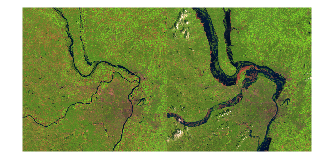

preflood = imread("stlouis_l5tm_14aug91_30m.jpg");
postflood = imread("stlouis_l5tm_19aug93_30m.jpg");
montage({preflood,postflood})

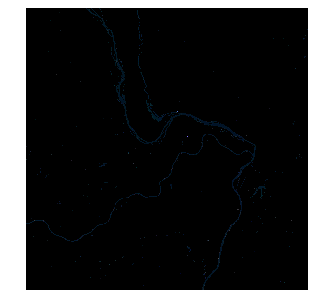


[BWpre, maskpre] = createMask(preflood);
imshow(maskpre)

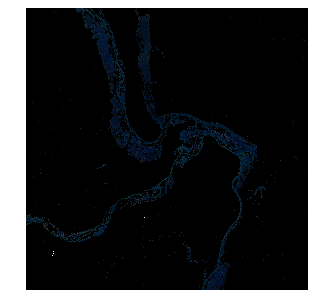


[BWpost, maskpost] = createMask(postflood);
imshow(maskpost)


nnz(BWpre);
nnz(BWpost);
(nnz(BWpost) - nnz(BWpre)) / nnz(BWpre) * 100;

fprintf('Area affected by floods before: %d\n', nnz(BWpre));

Area affected by floods before: 280685


fprintf('Area affected by floods after: %d\n', nnz(BWpost));

Area affected by floods after: 1057831


fprintf('Percentage increase in affected area: %d %%\n', (nnz(BWpost) - nnz(BWpre)) / nnz(BWpre) * 100);

Percentage increase in affected area: 2.768748e+02 %


function [BW,maskedRGBImage] = createMask(RGB)

I = rgb2hsv(RGB);

channel1Min = 0.5;
channel1Max = 0.745;

channel2Min = 0.000;
channel2Max = 1.000;

channel3Min = 0.000;
channel3Max = 1.000;

sliderBW = (I(:,:,1) >= channel1Min ) & (I(:,:,1) <= channel1Max) & (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
BW = sliderBW;

maskedRGBImage = RGB;

maskedRGBImage(repmat(~BW,[1 1 3])) = 0;

end